**Task:** Plot these data using any tool of your choice (Excel, Python, MATLAB, etc.).

file = readtable("Plane.csv")

file = 365×4 table
    Time      X        Y       Z  
    ____    _____    _____    ____

     502     0.13     0.46    1.01
     605    -0.01      0.4     0.9
     707    -0.02     0.43    0.91
     809    -0.05     0.35    0.87
     912    -0.02     0.37    0.68
    1014        0     0.33    0.43
    1117     0.39    -0.02    1.64
    1219     0.01      0.1    1.25
    1321    -0.05      0.1    1.08
    1424     0.11    -0.09    0.92
    1526     0.01     0.22    1.07
    1629        0      0.3    1.21
    1731    -0.18     0.23    1.28
    1833    -0.01     0.24    1.03
    1936    -0.02      0.2    0.89
    2038    -0.03    -0.01     0.8



t = table2array(file(:, "Time"));
x = table2array(file(:, "X"));
y = table2array(file(:, "Y"));
z = table2array(file(:, "Z"));

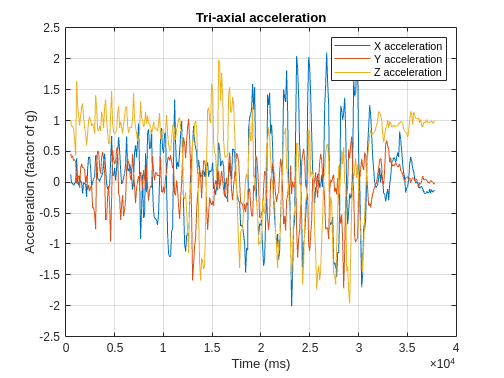

figure
plot(file,"Time",["X", "Y", "Z"])
legend(["X acceleration", "Y acceleration", "Z acceleration"])
title("Tri-axial acceleration")
ylabel("Acceleration (factor of g)")
xlabel("Time (ms)")
grid on

Use these values to estimate the displacement of the accelerometer and plot displacement on a separate graph.

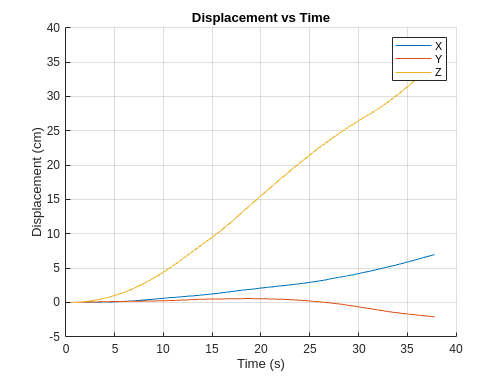

% X-axis
v_x = cumtrapz(t, x); % Integrate acceleration to get velocity
d_x = cumtrapz(t, v_x); % Integrate velocity to get displacement

% Y-axis
v_y = cumtrapz(t, y);
d_y = cumtrapz(t, v_y);

% Z-axis
v_z = cumtrapz(t, z);
d_z = cumtrapz(t, v_z);

figure
hold on;
plot(t/1e3, d_x/1e7) % convert to second and centimeter
plot(t/1e3, d_y/1e7)
plot(t/1e3, d_z/1e7)
hold off;
grid on;
xlabel('Time (s)');
ylabel('Displacement (cm)');
title('Displacement vs Time');
legend('X', 'Y', 'Z');

**Task:** Choose a suitable value of N and write a moving average filter. Run your data through it. Plot this against the raw (unfiltered) signal. What are the benefits/drawbacks of having a high N compared to a low N? 

N = 12

N = 12

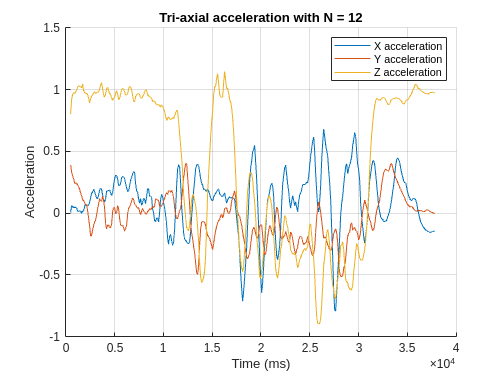


x_mm = movmean(x, N);
y_mm = movmean(y, N);
z_mm = movmean(z, N);

figure;
hold on;
plot(t, x_mm)
plot(t, y_mm)
plot(t, z_mm)
hold off;
grid on;
legend(["X acceleration", "Y acceleration", "Z acceleration"])
title(sprintf("Tri-axial acceleration with N = %d", N))
ylabel("Acceleration (factor of g)")
xlabel("Time (ms)")

N = 40

N = 40

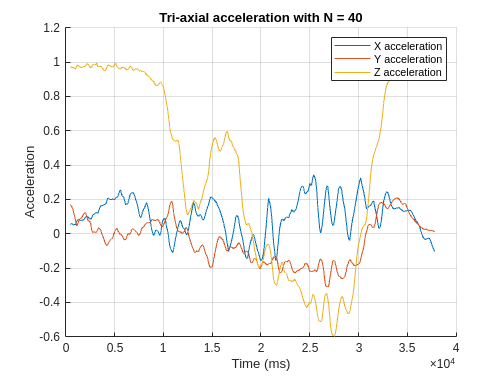


x_mm = movmean(x, N);
y_mm = movmean(y, N);
z_mm = movmean(z, N);

figure;
hold on;
plot(t, x_mm)
plot(t, y_mm)
plot(t, z_mm)
hold off;
grid on;
legend(["X acceleration", "Y acceleration", "Z acceleration"])
title(sprintf("Tri-axial acceleration with N = %d", N))
ylabel("Acceleration (factor of g)")
xlabel("Time (ms)")